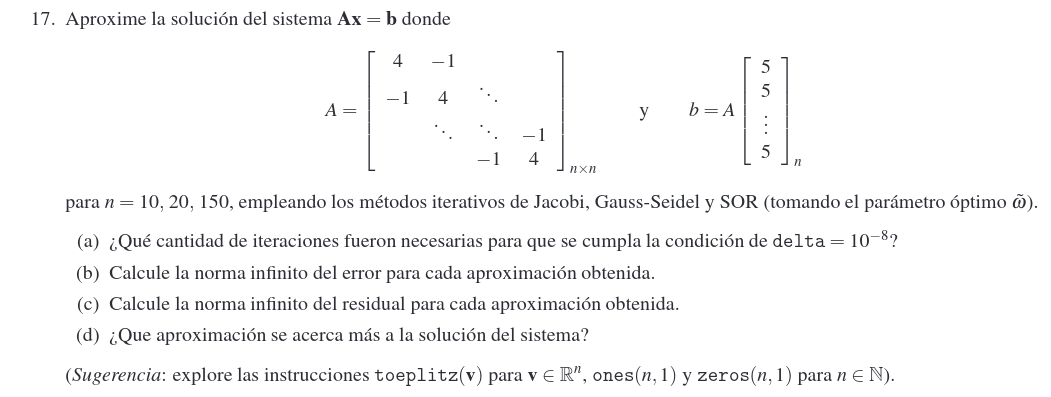

n = 10

n = 10

B = 5*ones(n,1)

B =      5
     5
     5
     5
     5
     5
     5
     5
     5
     5


I = diag(diag(4 * ones(n,n)))

I =      4     0     0     0     0     0     0     0     0     0
     0     4     0     0     0     0     0     0     0     0
     0     0     4     0     0     0     0     0     0     0
     0     0     0     4     0     0     0     0     0     0
     0     0     0     0     4     0     0     0     0     0
     0     0     0     0     0     4     0     0     0     0
     0     0     0     0     0     0     4     0     0     0
     0     0     0     0     0     0     0     4     0     0
     0     0     0     0     0     0     0     0     4     0
     0     0     0     0     0     0     0     0     0     4


L = triu((-1 * ones(n))) - triu((-1 * ones(n)),-1); 
L = L * -1

L =      0     0     0     0     0     0     0     0     0     0
    -1     0     0     0     0     0     0     0     0     0
     0    -1     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0
     0     0     0    -1     0     0     0     0     0     0
     0     0     0     0    -1     0     0     0     0     0
     0     0     0     0     0    -1     0     0     0     0
     0     0     0     0     0     0    -1     0     0     0
     0     0     0     0     0     0     0    -1     0     0
     0     0     0     0     0     0     0     0    -1     0


U = tril((-1 * ones(n))) - tril((-1 * ones(n)),1);
U = U * -1

U =      0    -1     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0
     0     0     0    -1     0     0     0     0     0     0
     0     0     0     0    -1     0     0     0     0     0
     0     0     0     0     0    -1     0     0     0     0
     0     0     0     0     0     0    -1     0     0     0
     0     0     0     0     0     0     0    -1     0     0
     0     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0     0    -1
     0     0     0     0     0     0     0     0     0     0


A = I+L+U

A =      4    -1     0     0     0     0     0     0     0     0
    -1     4    -1     0     0     0     0     0     0     0
     0    -1     4    -1     0     0     0     0     0     0
     0     0    -1     4    -1     0     0     0     0     0
     0     0     0    -1     4    -1     0     0     0     0
     0     0     0     0    -1     4    -1     0     0     0
     0     0     0     0     0    -1     4    -1     0     0
     0     0     0     0     0     0    -1     4    -1     0
     0     0     0     0     0     0     0    -1     4    -1
     0     0     0     0     0     0     0     0    -1     4



eig(A)

ans =     2.0810
    2.3175
    2.6903
    3.1692
    3.7154
    4.2846
    4.8308
    5.3097
    5.6825
    5.9190



x0 = ones(n,1);

J = -inv(I)*(U+L);
Pj = max(abs(eig(J)));
W = 2 / (1 + sqrt(1 - Pj^2));

X = jacobi (A, B,x0, 10e-8, 100)

k = 22

err = 4.3306e-07

X =     1.8301
    2.3205
    2.4518
    2.4869
    2.4956
    2.4956
    2.4869
    2.4518
    2.3205
    1.8301



Z = gseid (A, B, x0, 10e-8, 100)

k = 14

Z =     1.8301
    2.3205
    2.4518
    2.4869
    2.4956
    2.4956
    2.4869
    2.4518
    2.3205
    1.8301



Y = sor (A, B, x0, W, 10e-8, 100)

k = 11

Y =     1.8301
    2.3205
    2.4518
    2.4869
    2.4956
    2.4956
    2.4869
    2.4518
    2.3205
    1.8301


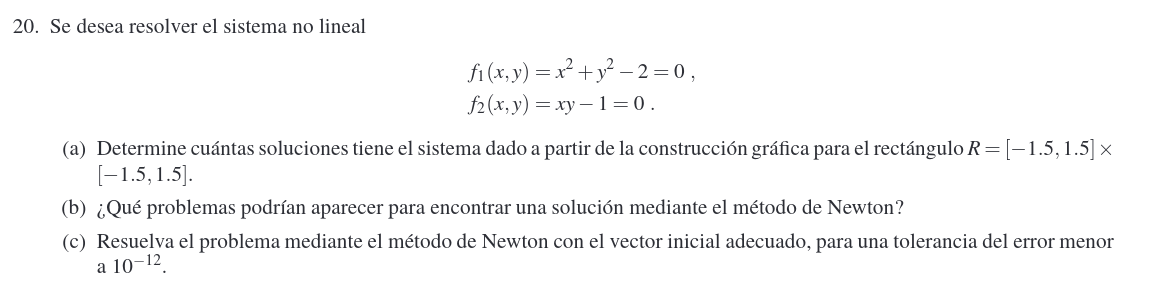

clf
clear
syms f1(x,y)
syms f2(x,y)

f1(x,y) = x^2 + y^2 - 2

$$f1(x, y) = x^{2}+y^{2}-2$$

f2(x,y) = x*y - 1

$$f2(x, y) = x\,y-1$$


f1 = matlabFunction(f1(x,y))

f1 = function_handle with value:
    @(x,y)x.^2+y.^2-2.0


f2 = matlabFunction(f2(x,y))

f2 = function_handle with value:
    @(x,y)x.*y-1.0



F = @(x) [(x(1)^2 + x(2)^2 - 2), (x(1)*x(2) - 1)]

F = function_handle with value:
    @(x)[(x(1)^2+x(2)^2-2),(x(1)*x(2)-1)]



ez1 = ezplot(f1, [-1.5 1.5],[-1.5, 1.5])

ez1 =   Contour with properties:

    EdgeColor: 'flat'
    LineStyle: '-'
    LineWidth: 0.5000
    FaceColor: 'none'
    LevelList: 0
        XData: [-1.5000 -1.4880 -1.4760 -1.4640 -1.4520 -1.4400 -1.4280 -1.4160 -1.4040 -1.3920 -1.3800 -1.3680 -1.3560 -1.3440 -1.3320 -1.3200 -1.3080 -1.2960 -1.2840 -1.2720 -1.2600 -1.2480 -1.2360 -1.2240 -1.2120 -1.2000 -1.1880 … ] (1×251 double)
        YData: [251×1 double]
        ZData: [251×251 double]

  Show all properties


hold on
grid on
ez2 = ezplot(f2, [-1.5 1.5],[-1.5, 1.5])

ez2 =   Contour with properties:

    EdgeColor: 'flat'
    LineStyle: '-'
    LineWidth: 0.5000
    FaceColor: 'none'
    LevelList: 0
        XData: [-1.5000 -1.4880 -1.4760 -1.4640 -1.4520 -1.4400 -1.4280 -1.4160 -1.4040 -1.3920 -1.3800 -1.3680 -1.3560 -1.3440 -1.3320 -1.3200 -1.3080 -1.2960 -1.2840 -1.2720 -1.2600 -1.2480 -1.2360 -1.2240 -1.2120 -1.2000 -1.1880 … ] (1×251 double)
        YData: [251×1 double]
        ZData: [251×251 double]

  Show all properties


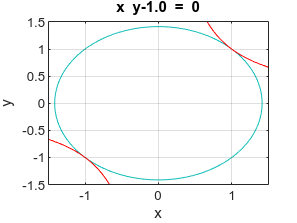

set(ez2,'color',[1 0 0])




dfx1 = diff(f1,x)

$$dfx1 = 2\,x$$

dfy1 = diff(f1,y)

$$dfy1 = 2\,y$$

dfx2 = diff(f2,x)

$$dfx2 = y$$

dfy2 = diff(f2,y)

$$dfy2 = x$$


JF = @(x)[2*x(1) * 2*x(2); x(2) * x(1)]

JF = function_handle with value:
    @(x)[2*x(1)*2*x(2);x(2)*x(1)]


p0= [-1 -0.5]

p0 =    -1.0000   -0.5000



[P, iter, err] = newdim (F, JF,p0, 10e-100, 10e-100, 100)

P =     0.7254    1.2254


iter = 36

err = 0


sol = feval(F,P)

sol =     0.0278   -0.1111



norm(sol,1)

ans = 0.1389